# Shortest Vector Problem (SVP)

Como se explicó en el paper

format long
f = @(x) -(0.5)*log(1-cos(x))-0.099;

%Rango de valores de x, desde 1 hasta 63 grados
x_data = linspace(1, 63, 15);


%Conversión de unidades - Grados sexagesimales a radianes:
x_data = x_data * pi / 180;

%Evaluamos los puntos en la funcion brindada
y_data = f(x_data);

%Tabla con los puntos utilizados a partir de la función continua

datos_tabla = table(x_data', y_data', 'VariableNames', {'phi', 'c=f(phi)'});

% Mostrar la tabla en la consola
disp(datos_tabla);

           phi                c=f(phi)     
    __________________    _________________

    0.0174532925199433     4.29581324774559
    0.0947464451082636      2.6044986096703
     0.172039597696584     2.00883773839417
     0.249332750284904     1.63913214581001
     0.326625902873225     1.37096252650201
     0.403919055461545     1.16092157736159
     0.481212208049865    0.988687752656778
     0.558505360638185     0.84309561514482
     0.635798513226506    0.717347588466876
     0.713091665814826    0.606996895632992
     0.790384818403146    0.508975303886346
     0.867677970991467    0.421076795337779
     0.944971123579787    0.341662465343866
      1.02226427616811    0.269481830561133
      1.09955742875643    0.203559451822093




plot(x_data, y_data, 'o')
xlabel('Ángulo phi entre 2 vectores (rad)');
ylabel('Complejidad');
hold on;
grid on;
title('Gráfica de la función continua');

Gráfico de la función continua

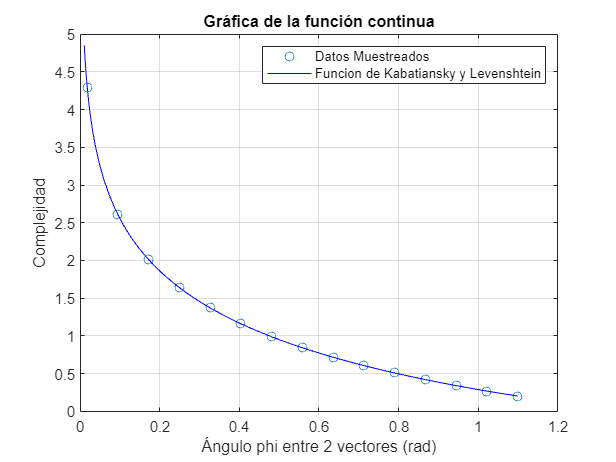

fplot(f, [0.01,0.35*pi],"-b")
legend('Datos Muestreados', 'Funcion de Kabatiansky y Levenshtein');
hold off;

Ajuste por mínimos cuadrados

% Grado del polinomio de aproximación (más alto más exacto)
n = 5;

% Coeficientes del ajuste polinomial por mínimos cuadrados
coefficients = polyfit(x_data, y_data, n);

% Mostrar los coeficientes en pantalla
disp('Coeficientes del polinomio de grado: ');

Coeficientes del polinomio de grado: 


disp(n);

     5



disp(coefficients);

   1.0e+02 *

  -0.404213823670202   1.312074394076432  -1.608811091585995   0.935257066038540  -0.277745293750292   0.046867785321927





% Calcular los valores del polinomio dado por el ajuste en nuestro rango de
% valores original
y_approx = polyval(coefficients, x_data);

% Error 
disp("Calculo del error:")

Calculo del error:


% Calcular el MSE
mse = mean((y_data - y_approx).^2);
% Calcular el coeficiente de determinación R^2
r_squared = 1 - ssr / sum((y_data - mean(y_data)).^2);
disp(['Error Cuadrático Medio (MSE): ' num2str(mse)]);

Error Cuadrático Medio (MSE): 0.0038096


disp(['Coeficiente de determinación R^2: ' num2str(r_squared)]);

Coeficiente de determinación R^2: 0.99661


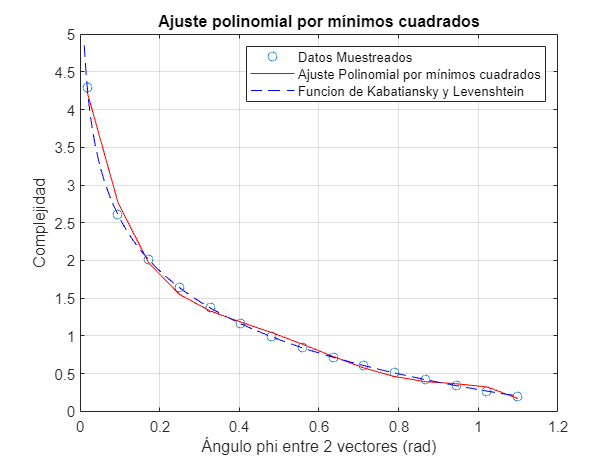



%Comparar el gráfico del ajuste polinomial con el de la función continua.
plot(x_data, y_data, 'o')
xlabel('Ángulo phi entre 2 vectores (rad)');
ylabel('Complejidad');
hold on;
grid on;
title('Ajuste polinomial por mínimos cuadrados');
plot(x_data, y_approx, '-r');
fplot(f, [0.01,0.35*pi],"--b");
legend('Datos Muestreados',  "Ajuste Polinomial por mínimos cuadrados",'Funcion de Kabatiansky y Levenshtein');
hold off;

Spline natural

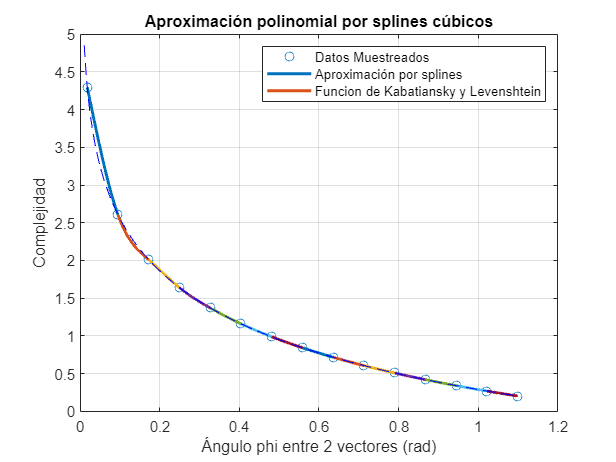


%Comparar el gráfico de la aproximacion polinomial por splines con el de la función continua.
plot(x_data, y_data, 'o')
xlabel('Ángulo phi entre 2 vectores (rad)');
ylabel('Complejidad');
hold on;
spline = splinenatural(x_data,y_data);
fplot(f, [0.01,0.35*pi],"--b");
title('Aproximación polinomial por splines cúbicos');
legend("Datos Muestreados", "Aproximación por splines", 'Funcion de Kabatiansky y Levenshtein');
hold off;

Lagrange

% Hallamos los coeficientes (será un polinomio de grado igual al número de
% puntos brindados)
coeficientes = lagrange(x_data,y_data);
disp('Coeficientes del polinomio de grado: ');

Coeficientes del polinomio de grado: 


disp(length(x_data));

    15



disp(coeficientes);

   1.0e+06 *

   0.017233101541442  -0.144696560348095   0.552750178375511  -1.271869176932919   1.966976817039229  -2.160107677805721   1.734940670843015  -1.034098664901252   0.459273418533590  -0.151267975464234   0.036460593022299  -0.006292300031986   0.000757219359011  -0.000064575842358   0.000005222514856





pol_lagrange = polyval(coeficientes, x_data)

pol_lagrange =    4.295813247745636   2.604498609670531   2.008837738385904   1.639132145748466   1.370962526473910   1.160921575945904   0.988687755538272   0.843095617414300   0.717347611775677   0.606997026308374   0.508975730719545   0.421077934963421   0.341665326591167   0.269488434514328   0.203573767531156



% Error 
disp("Calculo del error:")

Calculo del error:



% Calcular el error cuadrático medio (MSE)
mse = mean((y_data - pol_lagrange).^2);

% Mostrar el MSE
disp(['Error Cuadrático Medio (MSE): ' num2str(mse)]);

Error Cuadrático Medio (MSE): 1.7216e-11


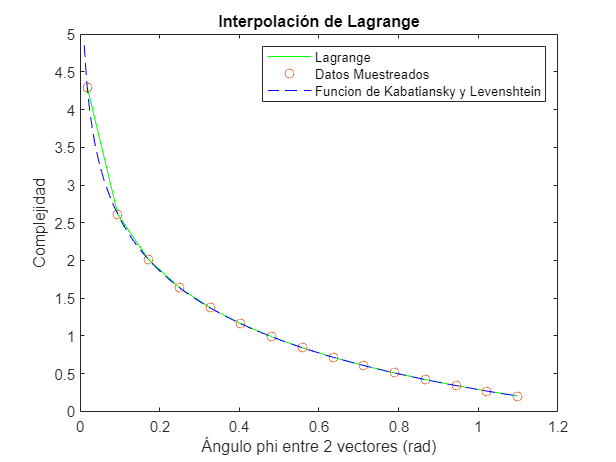


%Comparar el gráfico de la interpolación de Lagrange con el de la función continua.
plot(x_data, pol_lagrange, "g");
hold on
plot(x_data, y_data, 'o')
xlabel('Ángulo phi entre 2 vectores (rad)');
ylabel('Complejidad');
fplot(f, [0.01,0.35*pi],"--b");
title('Interpolación de Lagrange');
legend("Lagrange", "Datos Muestreados", 'Funcion de Kabatiansky y Levenshtein');
hold off



%pol_y = polyval(coeficientes, xx)

%plot(xx, pol_y, "g")

Función Spline

function S=splinenatural(X,Y)
    N = length(X)-1;
    H = diff(X);
    E = diff(Y)./H;
    diagprinc = 2*(H(1:N-1)+H(2:N));
    diagsupinf = H(2:N-1);
    g0 = 0; gn = 0;
    A = diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1);
    b = 6*diff(E');
    g = A\b;
    g = [g0 g' gn];
    colors = lines(length(X));
    for i = 1:N
        S(i,1) = (g(i+1)-g(i))/(6*H(i));
        S(i,2) = g(i)/2;
        S(i,3) = E(i)-H(i)*(g(i+1)+2*g(i))/6;
        S(i,4) = Y(i);
        xx = linspace(X(i), X(i+1), 100);
        yy = S(i,1)*(xx-X(i)).^3+S(i,2)*(xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
        plot(xx,yy, 'LineWidth', 2,'Color',colors(i,:))
        hold on
    end
    grid on
    %hold off
end

Interpolación de Lagrange

function p = lagrange(x,y)
    n = length(x);
    p = zeros(1,n);

    for k = 1:n
        num = poly(x([1:k-1,k+1:n]));
        den = polyval(num,x(k));
        L = num/den;
        p = p + y(k)*L;
    end
end